annotation_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/mean_annotators/"

annotation_dir = "/home/akamath/Documents/miccaihackathon_shifts/data/mean_annotators/"

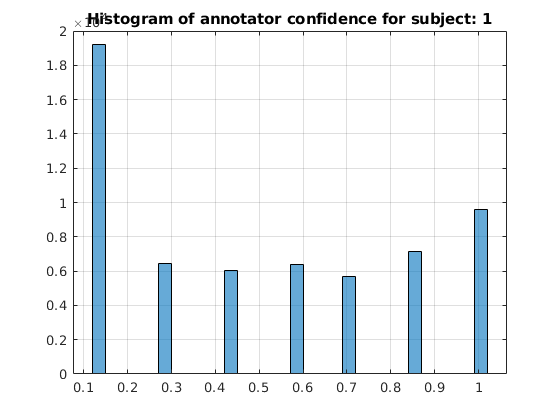

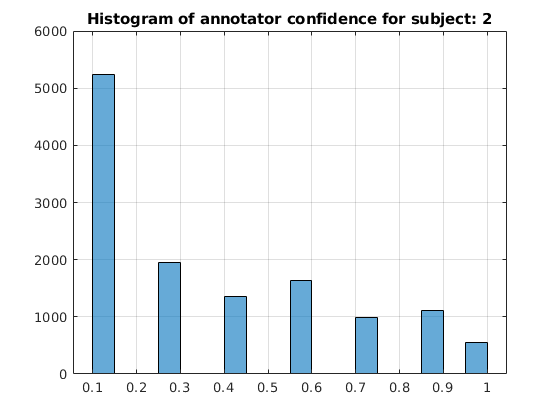

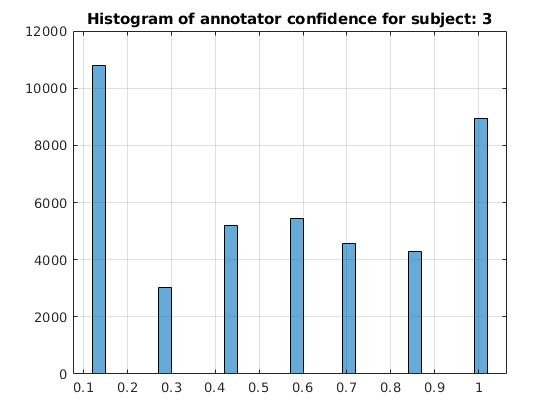

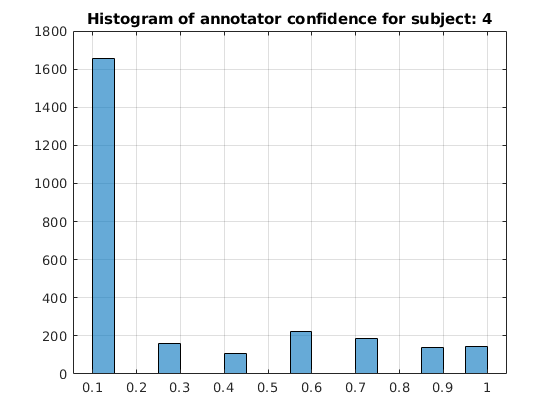

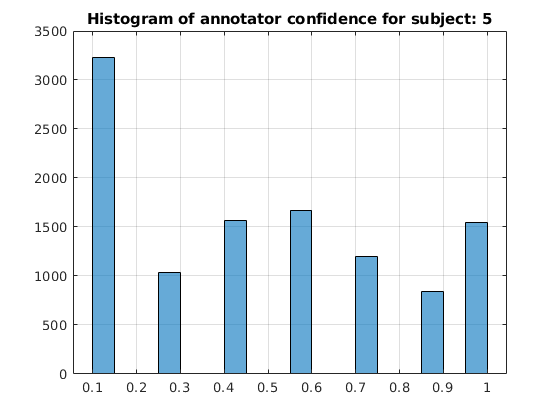

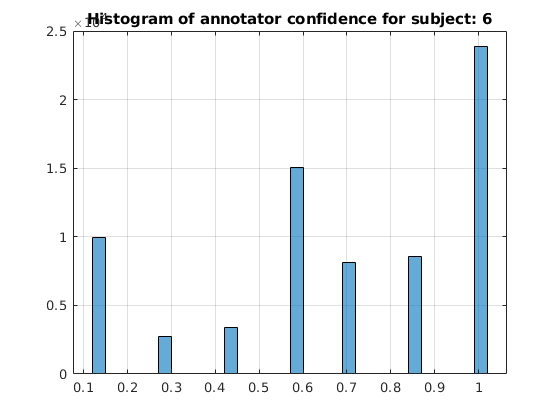

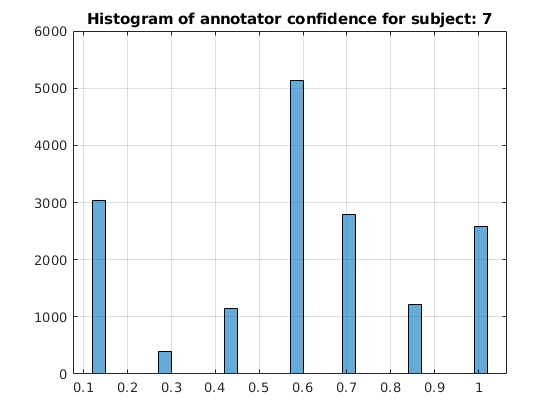

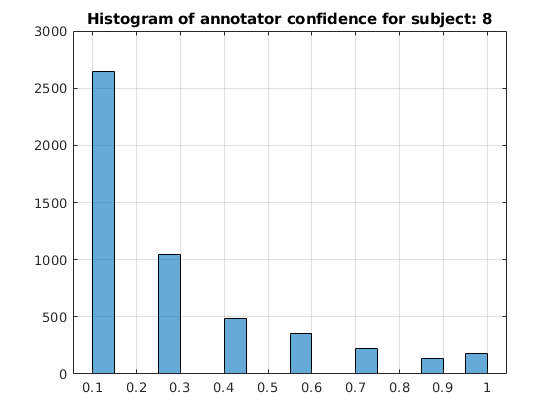


for idx = 1:24
    mean_ann_for_subject = fullfile(annotation_dir, string(idx) + "_mean_annotation.nii.gz");
    mean_data = niftiread(mean_ann_for_subject);
    figure, 
    fig = histogram(mean_data(mean_data > 0));
    title("Histogram of annotator confidence for subject: " + string(idx))
    grid on
    saveas(fig, fullfile(annotation_dir, string(idx) + "_histogram.png"));
end